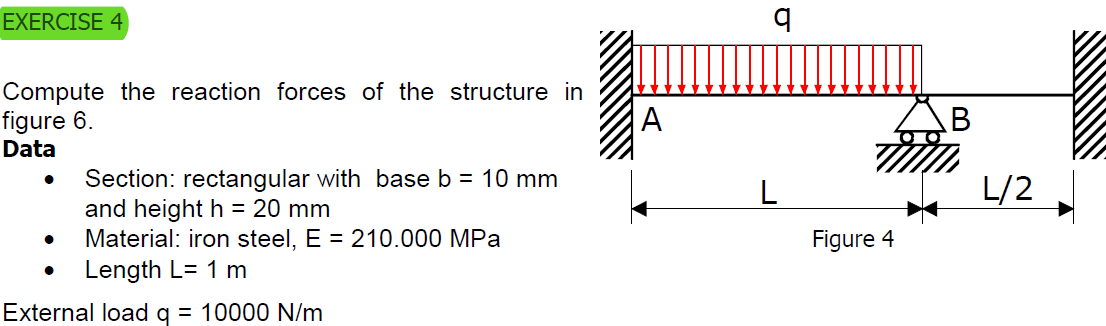

syms b h I E l P k Fs Ma Fa yb K phi2

b=10

b = 10

h=20

h = 20

I=b*h^3/12*10^-12

I = 6.6667e-09


E=210*10^9

E = 2.1000e+11

l1=1

l1 = 1

l2=0.5

l2 = 0.5000

L=1.5

L = 1.5000

q=10*10^3

q = 10000




K1 =(E*I/l1^3)*[     12 6*l1 -12 6*l1;
                 6*l1 4*l1^2 6*l1 2*l1^2;
                -12 -6*l1 12 -6*l1;
                6*l1 2*l1^2 -6*l1 4*l1^2;];
K1(:,1:3)=0;
K1

K1 =            0           0           0        8400
           0           0           0        2800
           0           0           0       -8400
           0           0           0        5600



K2 =(E*I/l2^3)*[     12 6*l2 -12 6*l2;
                 6*l2 4*l2^2 6*l2 2*l2^2;
                -12 -6*l2 12 -6*l2;
                6*l2 2*l2^2 -6*l2 4*l2^2;];
K2(:,1)=0;
K2(:,3:3)=0;
K2

K2 =            0       33600           0       33600
           0       11200           0        5600
           0      -33600           0      -33600
           0        5600           0       11200



phi2=25/98

phi2 = 0.2551

V1=K1(1,4)*phi2

V1 = 2.1429e+03

M1=K1(2,4)*phi2

M1 = 714.2857

V2=(K1(3,4)+K2(1,2))*phi2

V2 = 6.4286e+03

M2=K2(3,2)*phi2

M2 = -8.5714e+03

V3=K2(4,2)*phi2

V3 = 1.4286e+03

M3=(K1(4,4)+K2(2,2))*phi2

M3 = 4.2857e+03



% phi2=solve(V1+V2+V3==q*l1)  %go phi2 from here
